# YOUR TITLE HERE

*Authors:* MAKE SURE TO WRITE YOUR NAMES

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

*(Write your response here)*

## 1. Modeling Question

*(State your modeling question directly. Categorize it according to the action/specificity framework.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: we were curious about some question because of some reasons*

*B: but we weren't sure how to model it*

*T: so we did some background research for ideas (i.e. research synthesis matrix)*

    Our modeling question was how different demographics affect the spread of Covid-19 over time, as we were curious about how disease spread could be modeled with more realistic parameters, like having things like age and human interventions like vaccination will affect the spread of the disease, and if that was something that we could possibly track within our model. Because of this we created a interacting subpopulation SEIRVD model to expand upon the SIR-reinfectivity model that we were using previously to investigate disease spread, and Covid-19 data to allow us to measure our model in a real world scenario rather than with a simplistic model of disease spread, allowing us to see the effectiveness of our model if it would be used in real life.

    Our model is relatively specific, as we are focusing in specifically on Covid-19, and the differences in spread and severity between a older and a younger subpopulation. We are also including vaccination in our model as an important measure of human intervention in the spread of disease. Our model is relatively rhetorical, as there is not much of a usecase for this model at this point in time, as the Covid-19 pandemic ocurred 6 years ago -- which is crazy by the way -- and there are many models out there that would more quickly be able to estimate the spread and severity if a new strain of Covid reappeared. Our model does have a couple of key limitations that also apply to this being only for rhetorical purposes of comparing it to a standard SIR- reinfectivity model, with our model not accounting for disease evolution over time, such as new strains of the virus that have different affects on the populous, and other human interventions like masking and social distancing, leading to a model with significant flaws. Our model can also only predict based on past data, and as time has passed, most of the populous has gained a resistance to the disease over time, and it is significantly less prevalent, leading to our data not being as timely as we would like it to be.

## 2. Literature Search

*(Identify 3 or more scholarly articles that are relevant to your modeling question. Analyze these references using the synthesis matrix approach. Report your synthesis matrix in a readable format: Include a link to a Google Sheet if it does not fit in the report.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*A: we learned X from article 1, Y from article 2, and Z from article 3*

*B: but we didn't find a direct answer to our modeling question*

*T: so we went on to build a model*

*    We began our process by looking into multiple different possible model designs that we could make in order to much more accurately model how a disease would spread in reality. Through our research we decided that we wanted to focus in on having multiple subpopulations of data, which would allow us to have much more accuracy to diseases like Covid 19 that act very differently depending on things like the age of someone who is infected with the disease. We also really wanted to be able to measure things like vaccination, and have a period where a person could be exposed to the disease, and not yet be infected, but still pass it on to others. We also wanted to be able to account for deaths due to the disease, allowing us to more accurately maintain the system with people being reinfected after time has passed.*

[*https://precisionnanomedicine.com/article/26101-personalized-dose-covid-19-vaccination-in-a-wave-of-virus-variants-of-concern-trading-individual-efficacy-for-societal-benefit*](https://precisionnanomedicine.com/article/26101-personalized-dose-covid-19-vaccination-in-a-wave-of-virus-variants-of-concern-trading-individual-efficacy-for-societal-benefit) 

*    We then researched ways that this type of model has been implemented in the past, and found this paper looking into how different vaccination strategies would affect the spread of disease over a population. This paper had a model with interconnected subpopulations based on age, and also accounted for many of the things that we found most important for our model, leading us to base our design off of the one used in this paper. The paper was able to give us a lot of insight into the best way to run tests of our model, as they set up multiple different vaccination strategies, and ran simulations with each one, and measured the effects on the population based on that. Because of this we learned some methods of taking our raw data, and running different parameter sweeps over our system, and what we should target to be able to match our system more accurately to the real life data, being focusing on the values for people who have both recovered from the disease, and the people who have been vaccinated, as the groups who maintain the ability to transmit the disease, but are under less effects of it are really influential within our model.*

*PUT MORE SHIT HERE, INCLUDING TABLE*

## 3. Natural World

*(Describe the natural world using your 3 or more scholarly articles. Use an inline citation every time you refer to a fact from one of the scholarly articles. Everything you describe should be relevant to your modeling question. This section should connect to your tenchi diagram; we recommend putting the diagram directly between sections 3 and 4 since it serves as a transition between the two.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: here's a few things that are important in the natural world*

*B: but there are some things we assumed are not relevant to our modeling question*

*T: so, we left those things outside the system boundary (they are not modeled)*

*The natural world in our model is represented by two different populations, one of older individuals, and one of younger individuals. This allows us to more accurately measure the effects of Covid on the population as it is a disease that is significantly more effective in older individuals, and it has much more extreme effects, but there are significantly more cases in younger individuals who feel the effects much less than that of older people who catch the disease. Our model also is only focusing on the United States from the period of January 2020 through May 2023, as that is the range of the data that we were able to obtain of Covid cases in people.*

*    An important difference between our model and the natural world is that within our model we are assuming that the disease does not change and evolve over time, which is a key difference in comparison to real life in which a disease can come up with new strains rapidly that will get around current vaccines and built up immunity. Because we are ignoring diseases causing multiple strains we are losing out on some accuracy in favor of simplicity. In the same way we are also not accounting for human interventions such as masking and social distancing, as human intervention will vary wildly based off of location, perceived severity, and reccomendations from authority, and the randomness of humanity would make modeling significantly more complex, and we would lose out on being able to look specificly at different subpopulations as human intervention is often a universal aspect, where either all people in a subgroup are working to prevent disease transfer, or very few people in the subgroup are working to prevent transfer.*

*ADD IN THE REFERENCES HERE!!*

## 4. Model: Representation & Assumptions

*(Describe how your model represents the natural world. Use a tenchi diagram to illustrate what parts of the natural world are inside the system boundary. In the same tenchi diagram, provide a visual of your model. Describe in words how your model represents the chosen system. Describe in words what assumptions you have made. Cite your references when appropriate.)*

*(You will likely need to write 5-7 code & text regions for this section. You should have images and equations to describe your model, and then implement your model in code.)*

% Young people
Pcontact = 0.5; % From paper
Pinfectivity_semirisk = 0.0132; % 
Pinfectivity_risk = 0.35;
Precovered = 0.9965/7; % 1-deceased, divided by 7 since people are infectious for 7 days
Pdeceased = 0.0035/7; % Fatality rate
Pvaccinated = 0.0033; % 1 million vaccinations per day available for population of 300,000,000
    
numPostInfection = 19000000;
numVaccinated = 0;
numNaive = 258141000;
numInfectious = 1155000;
numDeceased = 0;

% Old people
Pcontact = 0.5;
Pinfectivity_semirisk = 0.0414;
Pinfectivity_risk = 0.35;
Precovered = 0.911/7;
Pdeceased = 0.089/7;
Pvaccinated = 0.0033;

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

Population counts grabbed from csv

*A: this part of the natural world is important for our question*

*B: but we can't include that directly because of X reason*

*T: so here is the way we represented it / what we assumed to simplify*

## 5. Verification & Validation

*(Select appropriate verification facts, and implement them as assert statements. In Projects 2 and 3, carry out model validation.)*

*(You will likely need to write 2-3 code sections for this section, and use words to describe your argument for verification and validation.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

assert(Pinfectivity_semirisk <= Pinfectivity_risk, "Vaccinated/post-infected people cannot be more infectious than infection-naive");
assert(Pcontact + Pvaccinated <= 1, "Flow exceeds stock quantity");
assert(Precovered + Pdeceased <= 1, "Flow exceeds stock quantity");

*A: here is a fact that should be true about the model*

*B: but it is not immediately obvious this is true, because X*

*T: so we carried out this test to show that it is true*

## 6. Claims & Limitations

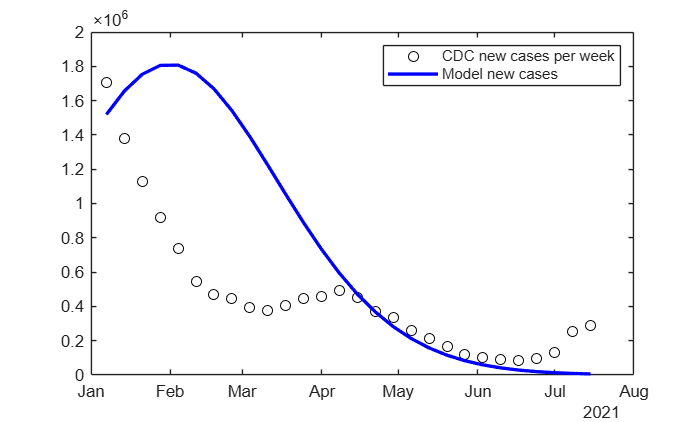

Vaccination has no time delay

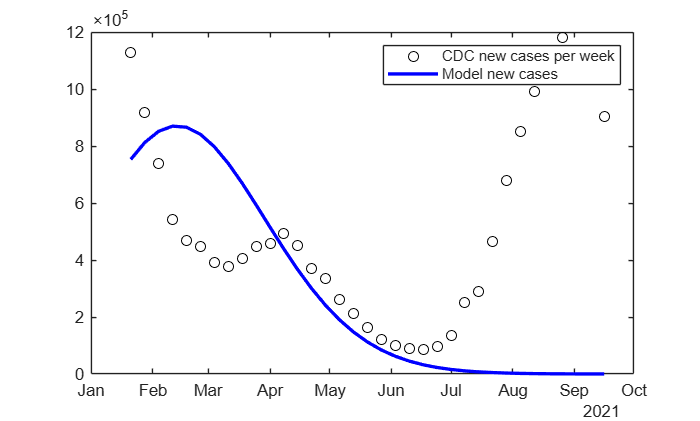

Vaccination has 10 days of delay

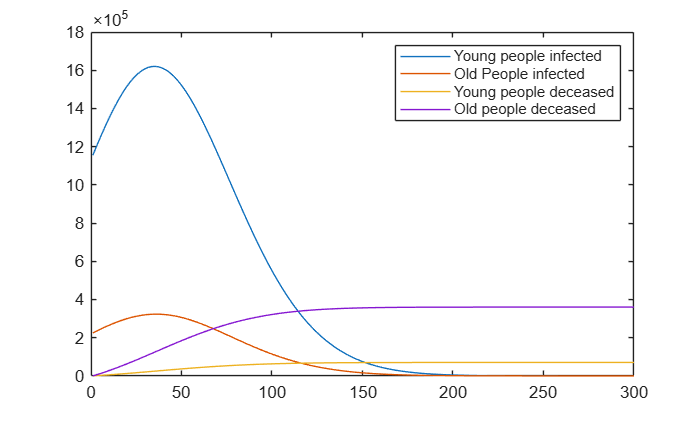

Observations:

We found that a lot more old people died than young people, even though there were a lot more infected young people. To see how each population affected the actual spread, we ran the model assuming both populations are the same.

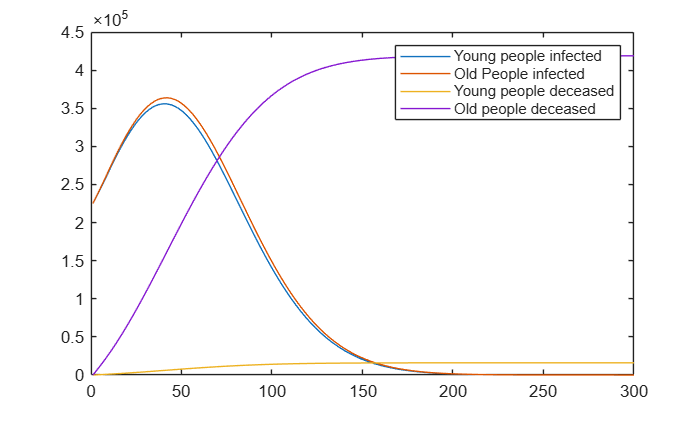

The curves we're nearly identical besides the fatality rate, which implies that population contact rates (the independent variable) does not greatly affect the transmission of disease. Rather, they both affect transmission equally, but only some populations are more affected by the disease itself (death rates/severe cases).

*(Run simulations using your model, and make claims about the natural world based on those results. Connect each assumption to a limitation about what you *cannot* conclude based on your model.)*

*(You will likely need to write 2-3 code sections for this section [generating results with your model], and 2-3 paragraphs making claims using your results, and discussing the limitations.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: remember this assumption from Section 4*

*B: but [our model still captures X important trend OR our question is about Y specifically OR our results are still informative because of Z]*

*T: so, we can conclude X, keeping in mind Y caveats*

## 7. Conclusion

*(Restate your modeling question, and refer to the claims from Section 6. Use your claims to directly answer your modeling question.)*

*(You will likely need just 1 paragraph for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important, and X is already known*

*B: but Y is not yet known, so we built a model to answer the question ...*

*T: so, given [particular result from Section 6], we conclude Z*

## 8. Future Work

*(Based on your limitations from Section 6, state 2 or more ideas of future work for other modelers to attempt.)*

*(You will likely need 2-3 paragraphs for this section.)*

*Work on breakthrough parameter that allows COVID to evolve into different strains that are more infectious. (but we could also do this for final draft)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: our model assumed X*

*B: but the natural world is actually like Y*

*T: so there are open questions, such as Z*

## References

*(List all references alphabetically by last name. Use the following format: Last name 1, Last name 2, ... (Year) "Title of Reference")*